# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Instru2\RawData_new'];    
Deci.SubjectList = 'gui';  
Deci.Step               =4; % Analysis;
Deci.PCom               = 0;                           % Activates Parallel Computing (if availible)
Deci.Proceed =    0;     
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Instru2\ProcessedData_new'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 54];
    Deci.DT.Toi        = [-2 3]; 

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =1;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3];
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 


Deci.Analysis.Var = 0;
Deci.Analysis.Clean = 1;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[23 31 51] [23 31 52] [23 32 51] [23 32 52]};
    
    %Deci.Plot.Lock = '2';
    %Deci.Plot.Conditions = {[23 31] [23 32]};
    Deci.Plot.GA = 0;

#### Math

Deci.Plot.Math.Form = {'[x2-x1]'};  
Deci.Plot.Math.Type = 0;

#### Time-Frequency

Deci.Plot.Freq.Foi = [3 inf];
Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'


## **6. Run**

----------------------
Starting Artifactor
searching for artifacts in 62 channels
searching in trial 480 from 480



detected 55 artifacts
the call to "ft_artifact_zvalue" took 99 seconds
searching for artifacts in 4 channels
searching in trial 480 from 480



detected 9 artifacts
the call to "ft_artifact_zvalue" took 16 seconds
detected  55 muscle artifacts
detected   9 eog artifacts
rejected   39 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 441 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 441 trials
showing a summary of the data for all channels and trials


computing metric [---|                                                     ]computing metric [------/                                                  ]computing metric [----------                                               ]computing metric [------------\                                            ]computing metric [---------------|                                         ]computing metric [------------------/                                      ]computing metric [----------------------                                   ]computing metric [-------------------------\                               ]computing metric [----------------------------|                            ]computing metric [-------------------------------/                         ]computing metric [-----------------------------------                      ]computing metric [-------------------------------------\                   ]computing metric [----------------------------------------|                ]computing me

417 trials marked as GOOD, 24 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 26, 28, 29, 161, 162, 163, 180, 218, 245, 246, 257, 258, 291, 313, 314, 318, 319, 371, 381, 382, 413, 414, 415, 431
the call to "ft_rejectvisual" took 52 seconds
the input is raw data with 62 channels and 417 trials
baseline correcting data 
scaling data with 1 over 73.636492
concatenating data.................................................................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x3719528
starting decomposition using runica

Input data size [20,3719528] = 20 channels, 3719528 frames/nAfter PCA 

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


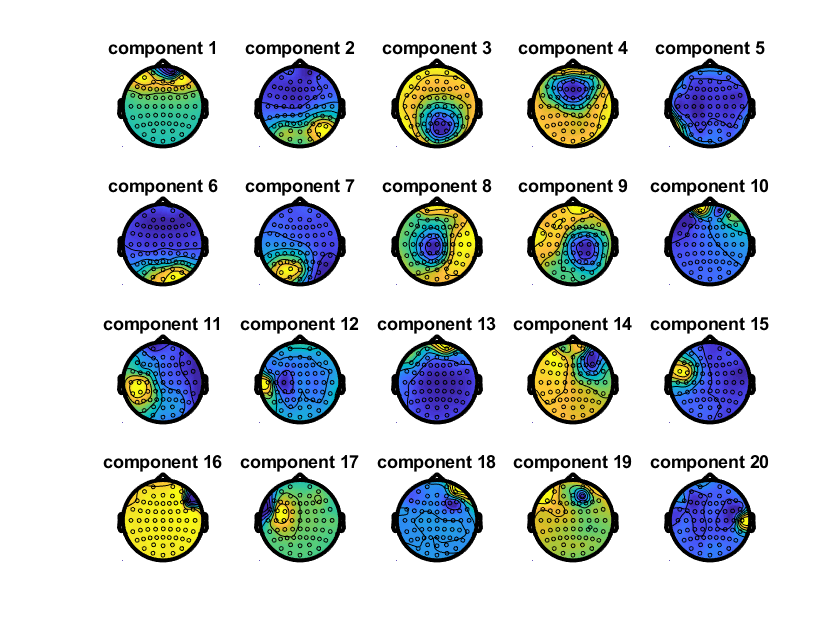

the call to "ft_topoplotIC" took 6 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 480 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 4 components
keeping 16 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


showing trial   1, channel Oz
detected 59 artifacts
the call to "ft_artifact_zvalue" took 104 seconds


showing trial   1, channel RHEOG
detected 21 artifacts
the call to "ft_artifact_zvalue" took 24 seconds
detected  59 muscle artifacts
detected  21 eog artifacts
rejected   44 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 436 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 436 trials
showing a summary of the data for all channels and trials


computing metric [---|                                                     ]computing metric [------/                                                  ]computing metric [----------                                               ]computing metric [------------\                                            ]computing metric [---------------|                                         ]computing metric [------------------/                                      ]computing metric [----------------------                                   ]computing metric [------------------------\                                ]computing metric [---------------------------|                             ]computing metric [------------------------------/                          ]computing metric [----------------------------------                       ]computing metric [------------------------------------\                    ]computing metric [----------------------------------------|                ]computing me

413 trials marked as GOOD, 23 trials marked as BAD
4 channels marked as GOOD, 58 channels marked as BAD
no channels were removed from the data
the following trials were removed: 25, 27, 28, 149, 150, 160, 161, 162, 179, 244, 245, 255, 256, 289, 311, 312, 316, 317, 369, 379, 380, 412, 413


the call to "ft_rejectvisual" took 71 seconds
the input is raw data with 62 channels and 413 trials
showing a summary of the data for all channels and trials


computing metric [---|                                                     ]computing metric [------/                                                  ]computing metric [----------                                               ]computing metric [------------\                                            ]computing metric [---------------|                                         ]computing metric [-------------------/                                     ]computing metric [-----------------------                                  ]computing metric [-------------------------\                               ]computing metric [----------------------------|                            ]computing metric [--------------------------------/                        ]computing metric [------------------------------------                     ]computing metric [--------------------------------------\                  ]computing metric [-----------------------------------------|               ]computing me

405 trials marked as GOOD, 8 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 37, 38, 155, 171, 300, 360, 389, 390


the call to "ft_rejectvisual" took 50 seconds


Finished Artifactor at 834.489
----------------------


Deci_Backend(Deci);